Signal to be Transmitted

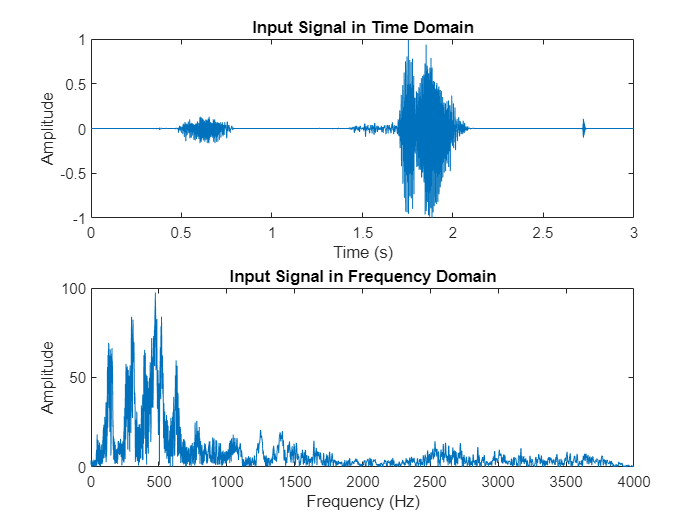

%Signal Generator

%fs = 8000;
%fc = 600; % Carrier frequency, Limit fc<800 to avoid freqdomain aliasing 
%nbits = 8; % 8 bits is enough;  
%audioduration = 3;
%ini_phase = 0; % Phase initial


%signal0 = audiorecorder(fs,nbits,1,0);% device id is zero (Default Mic)
%recordblocking(signal0,audioduration);
%speech_data = getaudiodata(signal0,'int16') % save as a int16 array
%input_signal_location = 'C:\Users\Xavier\Desktop\LBYEC4A\inputaudio.wav' 
%audiowrite(input_signal_location,speech_data,fs)

%input_audio = audioread('inputaudio.wav');

[inputaudio, Fs] = audioread('inputaudio.wav');

st = length(inputaudio);
time = st/Fs;
t = (0:1/Fs:time-1/Fs); %Time Domain
[Nf,P] = size(inputaudio);                 
f = (-Fs/2:Fs/(Nf-1):Fs/2);   
input_fft = fftshift(fft(inputaudio)); %Frequency Domain

subplot(211);
plot(t,inputaudio); %Time Domain
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Signal in Time Domain');

subplot(212);
plot(f,abs(input_fft)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(f)]);
title('Input Signal in Frequency Domain');

Encode the Analog Signal to Discrete Signal

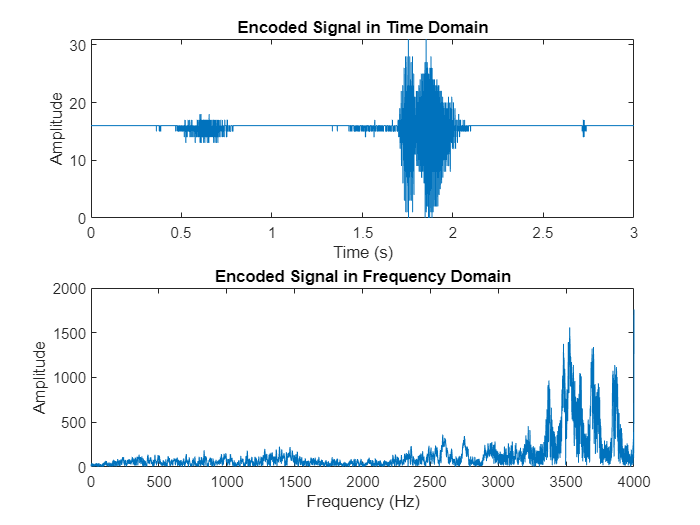

N = 5;
M = 2^N;
yy = uencode(inputaudio,N);

subplot(211);
plot(t,yy); %Time Domain
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal in Time Domain');

modfft = fft(yy);
subplot(212);
plot(f,abs(modfft)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(f)]);
title('Encoded Signal in Frequency Domain');

Modulate the Signal using QAM 32

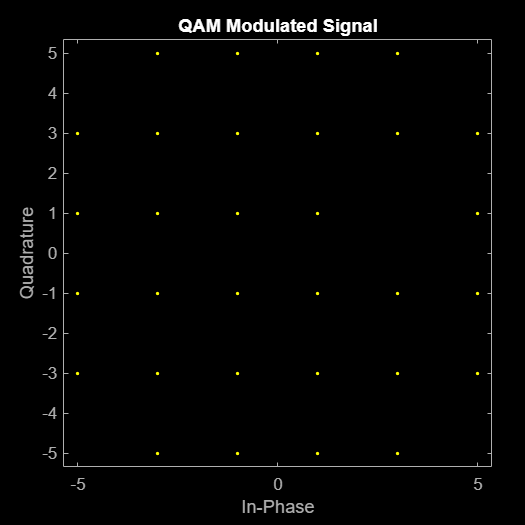

modulatedsig = qammod(yy,M);
scatterplot(modulatedsig);title('QAM Modulated Signal');

Create a Filter to limit the signal to the desired frequency band

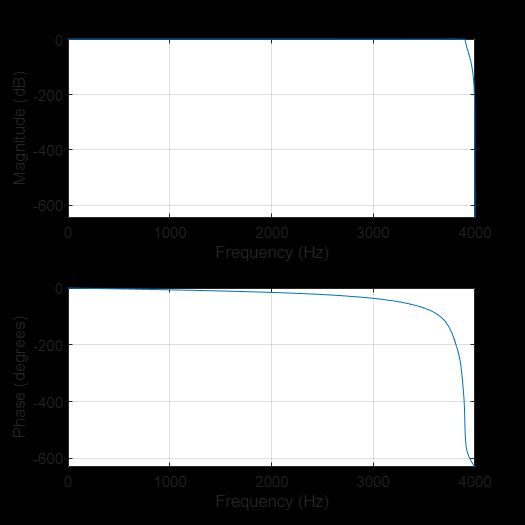

fs = 8000;
Fn = fs/2;
Wp = 3900/Fn;                                               
Ws = 3000/Fn;                                               
Rp =   1;                                                   
Rs = 150;                                                   
[n,Wn] = cheb1ord(Wp,Ws,Rp,Rs);                              
[z,p,k] = cheby1(n,Rp,Wn);   % Chebyshev 1 filter
[sosb,gb] = zp2sos(z,p,k); 
freqz(sosb, 2^20, Fs)     % Filter Bode Plot

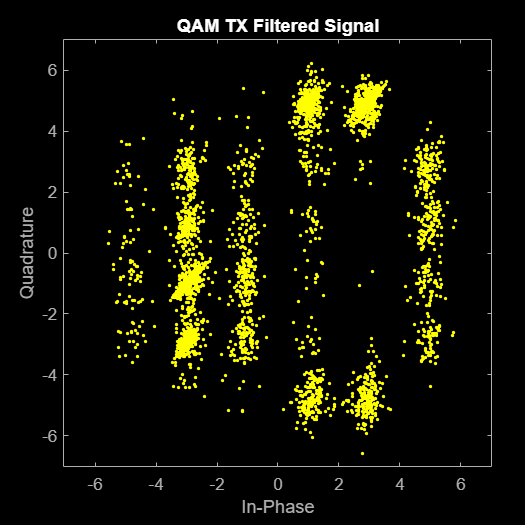

tx_filteredsig = filtfilt(sosb, gb, modulatedsig);
scatterplot(tx_filteredsig);title('QAM TX Filtered Signal');

Amplify the Signal for better transmission

tx_amplifiedsig = 3*tx_filteredsig;

Add Noise (show constellation diagram with different S/N)

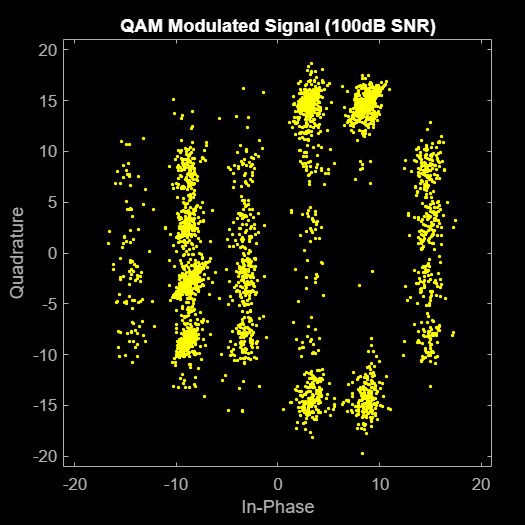

SNR0 = 100;
snr100 = awgn(tx_amplifiedsig, SNR0);
scatterplot(snr100);title('QAM Modulated Signal (100dB SNR)');

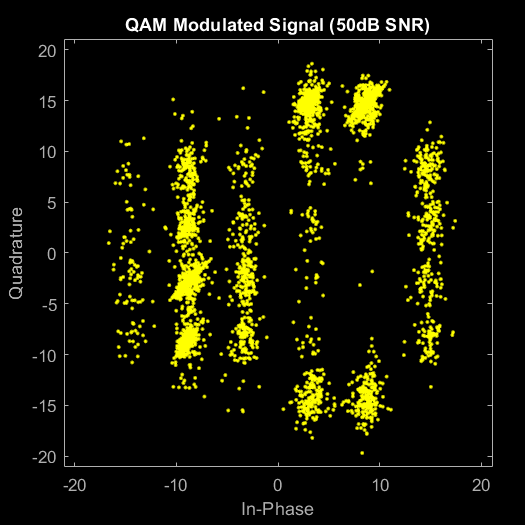

SNR1 = 50; 
snr50 = awgn(tx_amplifiedsig, SNR1);
scatterplot(snr50);title('QAM Modulated Signal (50dB SNR)');

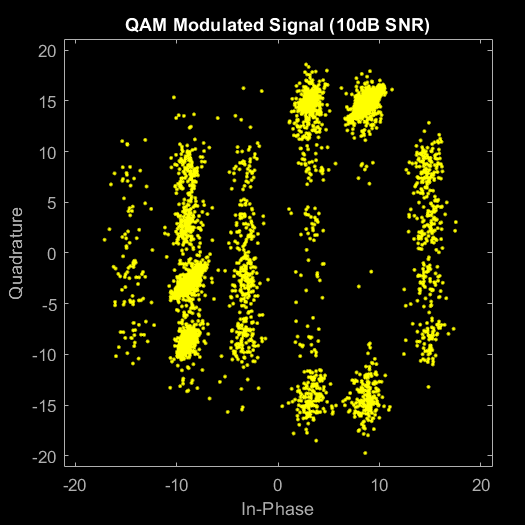


SNR2 = 10;
snr10 = awgn(tx_amplifiedsig, SNR2);
scatterplot(snr10);title('QAM Modulated Signal (10dB SNR)');

Filter the noisy signal 

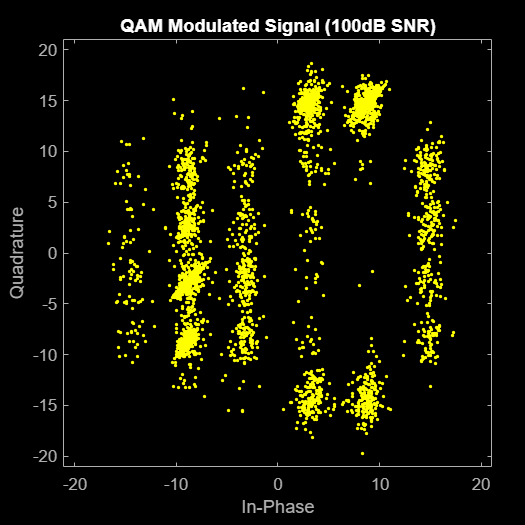

rx_filteredsignal100 =filter(Wn,n,snr100);
scatterplot(snr100);title('QAM Modulated Signal (100dB SNR)');

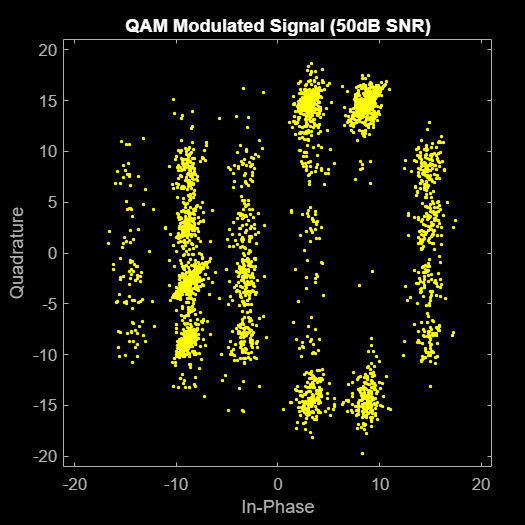

rx_filteredsignal50 =filter(Wn,n,snr50);
scatterplot(snr50);title('QAM Modulated Signal (50dB SNR)');

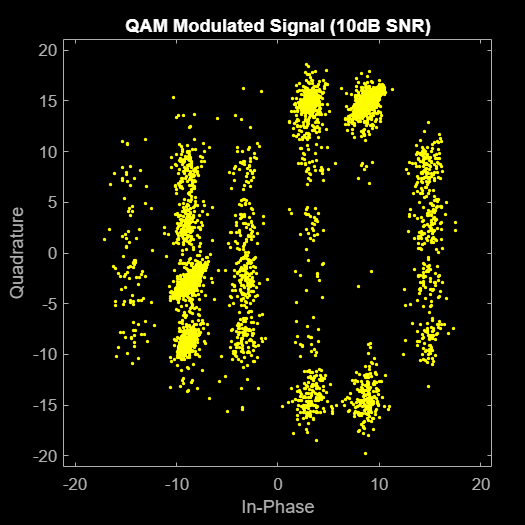

rx_filteredsignal10 = filter(Wn,n,snr10);
scatterplot(snr10);title('QAM Modulated Signal (10dB SNR)');

Recover the Noisy Signal for Comparison

Demodulatednoisysnr100 = qamdemod(rx_filteredsignal100,M);
Demodulatednoisysnr50 = qamdemod(rx_filteredsignal50,M);
Demodulatednoisysnr10 = qamdemod(rx_filteredsignal10,M);

Noisysnr100 = udecode(uint32(Demodulatednoisysnr100),N);
Noisysnr50 = udecode(uint32(Demodulatednoisysnr50),N);
Noisysnr10 = udecode(uint32(Demodulatednoisysnr10),N);

receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\noisysnr100.wav';
audiowrite(receivedsignalfile,Noisysnr100,fs);

receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\noisysnr50.wav';
audiowrite(receivedsignalfile,Noisysnr50,fs);

receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\noisysnr10.wav';
audiowrite(receivedsignalfile,Noisysnr10,fs);

Amplify the Signal

Amplifiedrx_filteredsignal100 = rx_filteredsignal100*3;
Amplifiedrx_filteredsignal50 = rx_filteredsignal50*3;
Amplifiedrx_filteredsignal10 = rx_filteredsignal10*3;

Demodulate the Signal

Demodulatedsnr100 = qamdemod(Amplifiedrx_filteredsignal100,M);
Demodulatedsnr50 = qamdemod(Amplifiedrx_filteredsignal50,M);
Demodulatedsnr10 = qamdemod(Amplifiedrx_filteredsignal10,M);

Compute the Bit Error Rate (BER)

[S0, R0] = biterr(Demodulatedsnr100,yy)

S0 = 576

R0 = 0.0048

[S1, R1] = biterr(Demodulatedsnr50, yy)

S1 = 577

R1 = 0.0048

[S2, R2] = biterr(Demodulatedsnr10, yy)

S2 = 645

R2 = 0.0054

Recover the Received Signal 

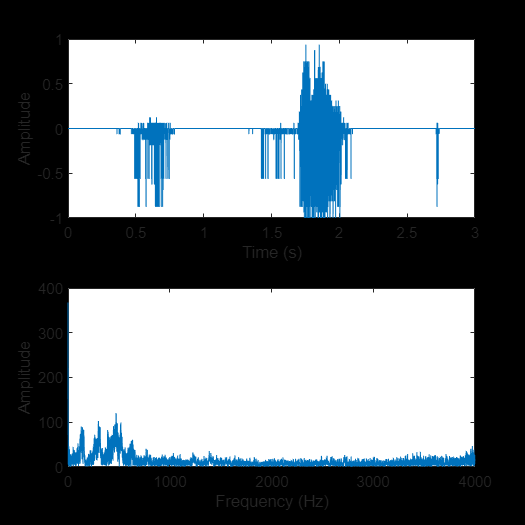

Recoveredsnr100 = udecode(uint32(Demodulatedsnr100),N);
Recoveredsnr50 = udecode(uint32(Demodulatedsnr50),N);
Recoveredsnr10 = udecode(uint32(Demodulatedsnr10),N);

% SNR = 100
subplot(2,1,1);
plot(t,Recoveredsnr100); %Time Domain
title('Recovered Signal (100dB SNR) in Time Domain');
xlabel('Time (s)');ylabel('Amplitude');

onehsnrFFT = fftshift(fft(Recoveredsnr50));
subplot(2,1,2);
plot(f,abs(onehsnrFFT)); %Frequency Domain
xlabel ('Frequency (Hz)');ylabel('Amplitude'); xlim([0 max(f)]); 
title('Recovered Signal (100dB SNR) in Frequency Domain');


receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\snr100.wav';
audiowrite(receivedsignalfile,Recoveredsnr100,fs);


% SNR = 50
subplot(2,1,1);
plot(t,Recoveredsnr50); %Time Domain
title('Recovered Signal (50dB SNR) in Time Domain');
xlabel('Time (s)');ylabel('Amplitude');

fiftysnrFFT = fftshift(fft(Recoveredsnr50));
subplot(2,1,2);
plot(f,abs(fiftysnrFFT)); %Frequency Domain
xlabel ('Frequency (Hz)');ylabel('Amplitude'); xlim([0 max(f)]); 
title('Recovered Signal (50dB SNR) in Frequency Domain');


receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\snr50.wav';
audiowrite(receivedsignalfile,Recoveredsnr50,fs);

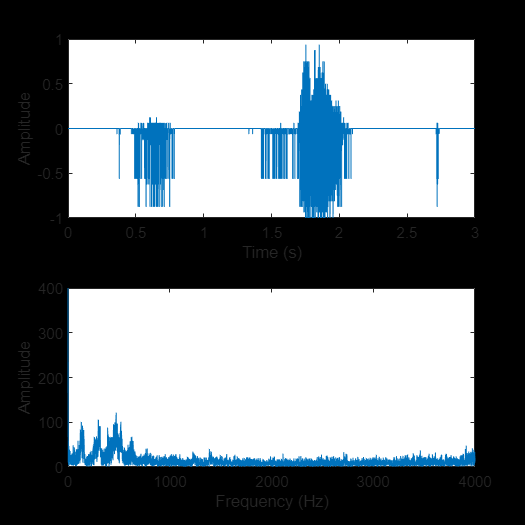


% SNR = 10
subplot(2,1,1);
plot(t,Recoveredsnr10); %Time Domain
xlabel('Time (s)');ylabel('Amplitude');
title('Recovered Signal (10dB SNR) in Time Domain');

tensnrFFT = fftshift(fft(Recoveredsnr10));
subplot(2,1,2);
plot(f,abs(tensnrFFT)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(f)]);
title('Recovered Signal (10dB SNR) in Frequency Domainn');


receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\snr10.wav';
audiowrite(receivedsignalfile,Recoveredsnr10,fs);